clear all

syms cc
taylor(exp(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}+\frac{{\mathrm{cc}}^{4}}{24}+\frac{{\mathrm{cc}}^{3}}{6}+\frac{{\mathrm{cc}}^{2}}{2}+\mathrm{cc}+1$$

taylor(sin(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}-\frac{{\mathrm{cc}}^{3}}{6}+\mathrm{cc}$$


taylor(exp(cc)) + taylor(sin(cc))+3*taylor(cos(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{60}+\frac{{\mathrm{cc}}^{4}}{6}-{\mathrm{cc}}^{2}+2\,\mathrm{cc}+4$$

input = 2*rand(1000,1)-1;
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

output = normalize(output);


datasize = length(input);
batchsize = 100;
minis = datasize/batchsize

minis = 10

decay =0.999

decay = 0.9990

alpha = 0.00001

alpha = 1.0000e-05

alfa = 0.001

alfa = 1.0000e-03

beta= 0

beta = 0

n=4

n = 4

eps = 10^-2

eps = 0.0100


V=zeros(batchsize,1) %momentum

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


B = 0.9

B = 0.9000

V1=0;
V2=0;
V3=0;
V4=0;

X = normalize(rand(n+1,4))/10;
ex= [0:n];

w1= X(:,1);
w2= X(:,2);
w3= X(:,3);



err(1:2)=1;
alfa = 0.0001

alfa = 1.0000e-04

% number of epochs
for i = 2:1000

% Learning rate
alpha=alfa %/(eps+err(i));  
alphas(i)=alpha;    
    
%divide data in batches
indexes= randperm(1000);
batchinput = reshape(input(indexes), [batchsize minis]);    
batchoutput = reshape(output(indexes), [batchsize minis]);

    for j = 1:minis
a1 = batchinput(:,j);
a2 = normalize(a1.^ex*w1);
a3 = normalize(a2.^ex*w2);
a4 = (a3.^ex*w3);

% meansa2(j) = mean(a2);
% meansa3(j) = mean(a3);
% stdsa2(j) = std(a2);
% stdsa3(j) = std(a3);
% a4 = a3.^ex*w3;
% % d4 = a4-batchoutput(:,j);
% d3 = d4 .* [zeros(batchsize,1) ones(batchsize,1) 2*a3 3*a3.^2 4*a3.^3] *w3;

d4 = a4-batchoutput(:,j);
grad3 = gradidi(a3,n);
grad2 = gradidi(a2,n);
grad1 = gradidi(a1,n);
d3 = d4 .* grad3 *w3;
d2 = d3 .* grad2 *w2;
d1 = d2 .* grad1 *w1;

% D = [d2;d1]

V4=B*V4 + (1-B)*d4;
V3=B*V3 + (1-B)*d3;
V2=B*V2 + (1-B)*d2;
V1=B*V1 + (1-B)*d1;

w3 = pinv((a3-beta*alpha*V3).^ex)*(a4-alpha*V4)*decay;
w2 = pinv((a2-beta*alpha*V2).^ex)*(a3-alpha*V3)*decay;
w1 = pinv((a1).^ex)*(a2-alpha*(V2))*decay;

    end

a1=input;
a2 = a1.^ex*w1;
a3 = a2.^ex*w2;
a4 = a3.^ex*w3;

err(i+1) = norm(a4-output)/norm(output);

if (err(i)<0.0001) ||(abs(err(i)-err(i-1))<0.0000001)
    disp("iterations: " + i)
     disp("error: " + err(i))
    break;
end 
end

alpha = 1.0000e-04

iterations: 2


error: 1


disp("error: " + err(i))

error: 1


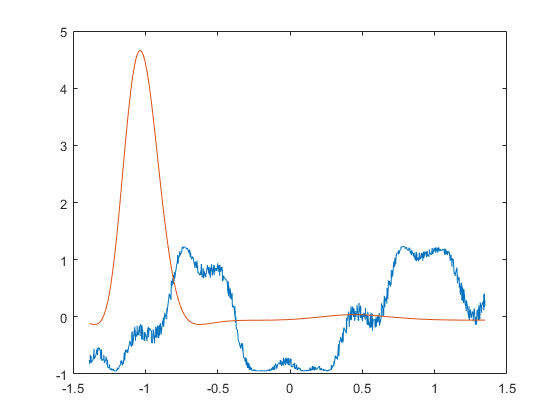


[B1,I] = sort(input);
B2 = output(I);

plot([B1 B1],[B2 a4(I)])

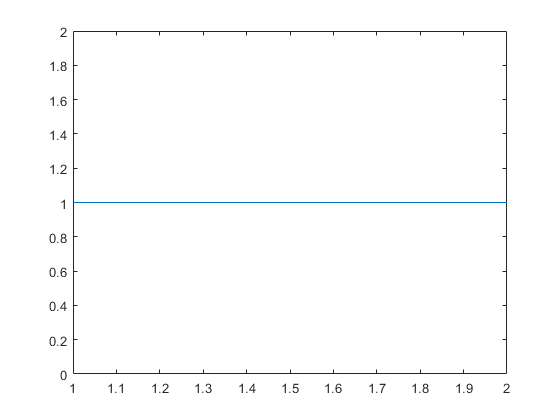


plot(err(1:i))

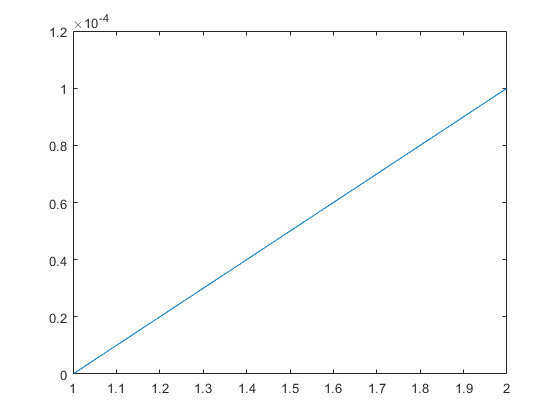

plot(alphas(1:i))


w1

w1 =     0.7066
    2.0551
   -2.0514
   -0.8571
    0.7973


w2

w2 =    -0.3831
   -0.0705
    0.2269
   -0.4587
   -0.0359


w3

w3 =    -0.1060
   -0.1075
    0.0510
    0.0794
    0.0772



ex=0:3

ex =      0     1     2     3


% zeros(1000,1) ones(1000,1)

w1 =  rand(4,1)

w1 =     0.7092
    0.6413
    0.1741
    0.0622


w2 =  rand(4,1)

w2 =     0.4067
    0.4631
    0.2027
    0.8695



a1 = input(1:200)

a1 =     0.7953
   -0.4229
   -0.4619
    0.1884
   -0.0482
   -0.2634
    0.3112
    0.8764
    0.2409
   -0.4343



a2 = a1.^ex*w1 

a2 =     1.3607
    0.4645
    0.4440
    0.8367
    0.6787
    0.5513
    0.9276
    1.4468
    0.8747
    0.4584



a3 = a2.^ex*w2

a3 =     3.6024
    0.7526
    0.7283
    1.4452
    1.0861
    0.8692
    1.7045
    4.1346
    1.5486
    0.7453




d3 = a3-output(1:200)

d3 =     2.2445
   -0.2530
   -0.5103
    2.7014
    2.2139
    1.0665
    1.6996
    3.4198
    2.5164
   -0.1845


d2 = d3 .* [zeros(200,1) ones(200,1) 2*a2 3*a2.^2] *w2

d2 =    13.1175
   -0.3072
   -0.5906
    7.0999
    4.2945
    1.5776
    5.2407
   22.2639
    7.0794
   -0.2209


d1 = d3 .* [zeros(200,1) ones(200,1) 2*a1 3*a1.^2] *w1

d1 =     2.3256
   -0.1335
   -0.2655
    1.9275
    1.3836
    0.6000
    1.3048
    3.7263
    1.8520
   -0.0969



w2 = pinv([a2-0.01*d2].^ex)*[a3-0.1*d3]*0.999

w2 =    -0.3039
    4.6777
   -7.8502
    5.4855


w1 = pinv(a1.^ex)*[a2-0.01*d2]*0.999

w1 =     0.6873
    0.6212
    0.0554
   -0.0773



% ---------
a2 = a1.^ex*w1;

a3 = a2.^ex*w2;

C = 0.5*(a3-output(1:200)).^2;
norm(C)/norm(output(1:200))

ans = 2.5951

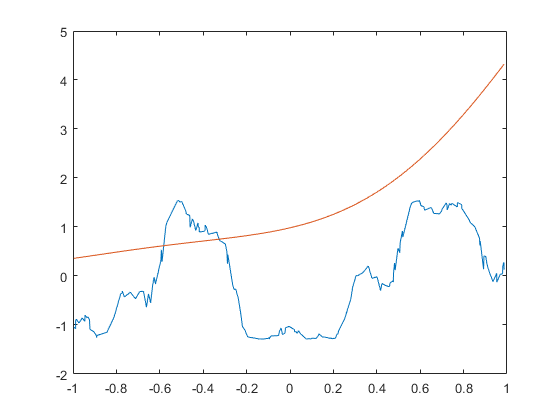




[B1,I] = sort(input(1:200));
B2 = output(I);

plot([B1 B1],[B2 a3(I)])


w1

w1 =     0.6873
    0.6212
    0.0554
   -0.0773


w2

w2 =    -0.3039
    4.6777
   -7.8502
    5.4855


ex= 0:10

ex =      0     1     2     3     4     5     6     7     8     9    10


input.^ex

ans =     1.0000    0.7953    0.6325    0.5030    0.4000    0.3182    0.2530    0.2012    0.1600    0.1273    0.1012
    1.0000   -0.4229    0.1788   -0.0756    0.0320   -0.0135    0.0057   -0.0024    0.0010   -0.0004    0.0002
    1.0000   -0.4619    0.2134   -0.0986    0.0455   -0.0210    0.0097   -0.0045    0.0021   -0.0010    0.0004
    1.0000    0.1884    0.0355    0.0067    0.0013    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000   -0.0482    0.0023   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000   -0.2634    0.0694   -0.0183    0.0048   -0.0013    0.0003   -0.0001    0.0000   -0.0000    0.0000
    1.0000    0.3112    0.0969    0.0301    0.0094    0.0029    0.0009    0.0003    0.0001    0.0000    0.0000
    1.0000    0.8764    0.7681    0.6731    0.5899    0.5170    0.4531    0.3971    0.3480    0.3050    0.2673
    1.0000    0.2409    0.0580    0.0140    0.0034    0.0008    0.0002    0.0000    0.0000    0.0000    0.

www = pinv(input.^ex)*(output);
output

output =     1.3579
    1.0056
    1.2387
   -1.2562
   -1.1277
   -0.1973
    0.0050
    0.7148
   -0.9677
    0.9299



[B1,I] = sort(input);
B2 = output(I);

recon = input.^ex*www

recon =     1.3518
    1.0906
    1.1868
   -0.9797
   -1.3655
   -0.0486
   -0.4494
    0.5466
   -0.7619
    1.1295


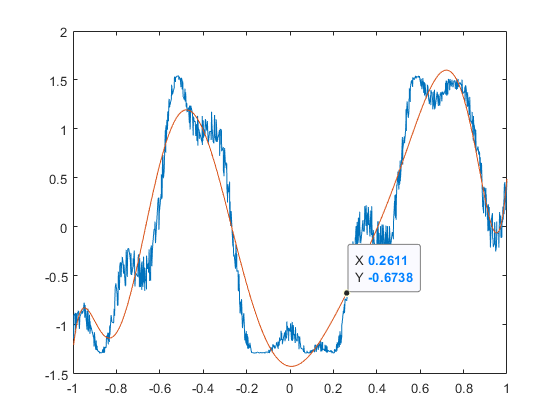


plot([B1 B1],[B2 recon(I)])


rataa = norm(recon-output)/norm(output)

rataa = 0.2828